n2 = 120

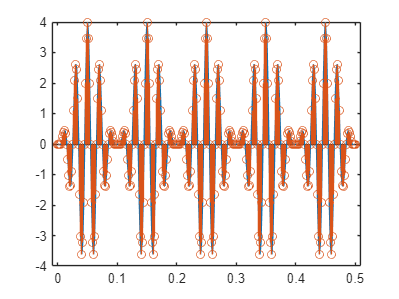

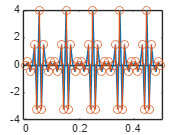

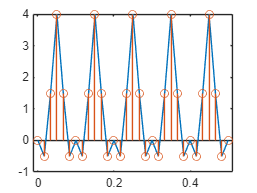

Current plot released


% Signal Generation and Visualization

% ----------------------------------
% This script defines variables and creates a time vector. It then generates 
% a composite signal `s1` by combining three cosine functions with different 
% frequencies. Finally, the script plots the continuous signal `s1` and 
% overlays it with a stem plot for discrete visualization.

n1 = 40;
n2 = 60*2 %max frequency
n3 = 50;

t = 0:1/(n2*5):0.5;

s1 = cos(80*pi*t) + cos(120*pi*t) - 2*cos(100*pi*t);

plot(t, s1)
hold on
stem(t, s1)
hold off


t = 0:1/(n2):0.5;
s2 = cos(80*pi*t) + cos(120*pi*t) - 2*cos(100*pi*t);

plot(t, s2)
hold on

stem(t, s2)
hold off


% Define time vector with finer resolution
t = 0:1/(n2/2):0.5;

% Generate composite signal
s3 = cos(80*pi*t) + cos(120*pi*t) - 2*cos(100*pi*t);

% Plot the signal
plot(t, s3)
hold on

% Overlay with stem plot
stem(t, s3)
hold 

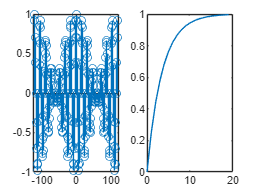

% 2. Dual Subplot Visualization
% --------------------------
% This script creates two subplots side by side.
% The first subplot plots a signal `x` based on cosine functions and a stem plot.
% The second subplot plots `h`, which is a combination of a unit step function
% and a decaying exponential, using the `plot` function.

% First subplot: Cosine-based signal
subplot(1,2,1)
n1 = -120:119;
x = cos(n1.*(pi/120)).*cos(n1.*(pi/8));
stem(n1, x)b

% Second subplot: Unit step and decaying exponential
subplot(1,2,2)
n2 = 0:19;
h = myunit(n2) - ((3/4).^(n2)).*mystep(n2);
plot(n2, h)

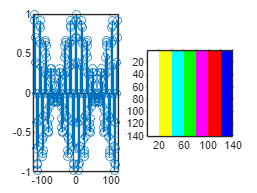

% Bar Pattern Image Creation and Visualization
% --------------------------------------------
% This script generates a horizontal bar pattern by defining a single line of 
% pixel values, replicating it vertically to create an image. The image is then 
% displayed with a custom colormap applied.

% Define the width of one bar in pixels
barWidth = 20;

% Create a single line of pixel values
oneLine = [zeros(1, barWidth), ones(1, barWidth), 2 * ones(1, barWidth), 3 * ones(1, barWidth), 4 * ones(1, barWidth), 5 * ones(1, barWidth), 6 * ones(1, barWidth)];

% Replicate the line vertically to create the full image
heightInPixels = 7 * barWidth;
indexedImage = repmat(uint8(oneLine), [heightInPixels, 1]);

% Display the image
imshow(indexedImage);

% Apply a custom colormap
customColorMap = [1 1 1;
  1 1 0;
  0 1 1;
  0 1 0;
  1 0 1;
  1 0 0;
  0 0 1];

colormap(customColorMap);
clim([0, 7]);

% Display the colorbar and axes
% colorbar;
axis on;

% Retrieve the audio file "tononoise8mono.wav"
[x, fs] = audioread('tononoise8mono.wav');

% Add a 1kHz tone with an amplitude of 0.4
f = 1000; % frequency of the tone
t = (1:length(x))/fs; % time vector
y = x + 0.4*sin(2*pi*f*t); % mixed signal

% Scale the mixed signal such that the maximum amplitude is 0.9
y = y./max(abs(y)).*0.9;

% Save the mixed signal as "myaudio.wav"
audiowrite('myaudio.wav', y(1,:), fs);